# IC widefield sound-evoked Cx26

% analysis widefield
defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\Widefield IC sound evoked';
cd(defaultDir);
addpath('452_3 tecta flfl','451_2 tecta flfl','299_3 tecta flfl','308_1 flfl','308_3 flfl','327_1 flfl','339_5 flfl','339_6 tecta fl+','342_2 flfl','344_1 tecta flfl','344_2 tecta flfl','347_1 tecta flfl','350_2 tecta flfl','386_3 tecta flfl','386_4 tecta flfl','412_2 tecta flfl','350_1 flfl','419_3 flfl')

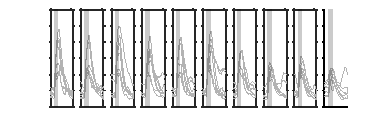

% 0 dB attenuation
% MAKE SEM
% played to L ear unless otherwise noted

% representation of sound is shifted more lateral in IC - what does this
% mean? no response to many low freqs.

% also, medial axis is more obvious in cKO. what could this possibly mean? 

% maybe changes in the traveling wave with anomalous cochlear
% amplification?

% 2P imaging probably wouldn't help much here

% ie sound representations are affected

cx261cko0db = load('299_3_0dB.mat'); % played to L ear, P15 
cx262cko0db = load('344_1_0dB.mat'); % played to R ear, P13
cx263cko0db = load('344_2_0dB.mat'); % played to R ear, P13
cx264cko0db = load('347_1_0dB.mat'); % played to R ear, P14/15
cx265cko0db = load('350_2_0dB.mat'); % played to R ear, P14/15
cx266cko0db = load('386_3_0dB.mat'); % L ear P14
cx267cko0db = load('386_4_0dB.mat'); % L ear P14
cx268cko0db = load('412_2_0dB.mat'); % L ear P14
cx269cko0db = load('451_2_0db.mat'); % P14 L ear 
cx2610cko0db = load('452_3_0db.mat'); %P14 R ear

con1db0 = load('308_1_0dB.mat'); % very low amplitude
con2db0 = load('327_1_0dBmoco.mat');
con3db0 = load('339_5_0dB.mat');
con4db0 = load('339_6_0dB.mat'); % high spontaneous activity, Cre+ het
con5db0 = load('342_2_0dB.mat');
con6db0 = load('308_3_0dB.mat'); % low amp
con7db0 = load('350_1_0dB.mat');

time = [1:1:length(cx261cko0db.avgLIC)];

for i = 1:16
    avgcko0db(i,:) = mean([cx261cko0db.avgRIC(i,:);cx262cko0db.avgLIC(i,:);cx263cko0db.avgLIC(i,:);cx264cko0db.avgLIC(i,:);cx265cko0db.avgLIC(i,:);cx266cko0db.avgRIC(i,1:56);cx267cko0db.avgRIC(i,1:56);cx268cko0db.avgRIC(i,1:56);cx269cko0db.avgRIC(i,1:56);cx2610cko0db.avgLIC(i,1:56);],1);
    stdcko0db(i,:) = std([cx261cko0db.avgRIC(i,:);cx262cko0db.avgLIC(i,:);cx263cko0db.avgLIC(i,:);cx264cko0db.avgLIC(i,:);cx265cko0db.avgLIC(i,:);cx266cko0db.avgRIC(i,1:56);cx267cko0db.avgRIC(i,1:56);cx268cko0db.avgRIC(i,1:56);cx269cko0db.avgRIC(i,1:56);cx2610cko0db.avgLIC(i,1:56);],1)/sqrt(10);
end

for i = 1:16
    avgCon0db(i,:) = mean([con1db0.avgRIC(i,:);con2db0.avgRIC(i,:);con3db0.avgRIC(i,:);con4db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgLIC(i,:)],1);
    stdCon0db(i,:) = std([con1db0.avgRIC(i,:);con2db0.avgRIC(i,:);con3db0.avgRIC(i,:);con4db0.avgRIC(i,:);con5db0.avgRIC(i,:);con6db0.avgRIC(i,:);con7db0.avgLIC(i,:)],1)/sqrt(7);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:10
    subplot(1,10,i);
    plot(con1db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    hold on
    plot(con2db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    plot(con3db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    plot(con4db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    plot(con5db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    plot(con6db0.avgRIC(i,:),'Color',l_grey,'LineWidth',0.5)
    plot(con7db0.avgLIC(i,:),'Color',l_grey,'LineWidth',0.5)
        patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

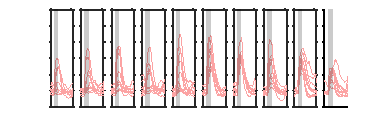

%print(gcf,'-dpdf')
figure
for i = 1:10
    subplot(1,10,i);
    %plot(time,avgCon0db(i,:),'k','LineWidth',1);
    plot(time,cx261cko0db.avgRIC(i,:),'color',l_red,'LineWidth',0.5)
    hold on
    plot(time,cx262cko0db.avgLIC(i,:),'color',l_red,'LineWidth',0.5)
    plot(time,cx263cko0db.avgLIC(i,:),'color',l_red,'LineWidth',0.5)
    plot(time,cx264cko0db.avgLIC(i,:),'color',l_red,'LineWidth',0.5)
    plot(time,cx265cko0db.avgLIC(i,:),'color',l_red,'LineWidth',0.5)
    plot(time,cx266cko0db.avgRIC(i,1:56),'color',l_red,'LineWidth',0.5)
    plot(time,cx267cko0db.avgRIC(i,1:56),'color',l_red,'LineWidth',0.5)
    plot(time,cx268cko0db.avgRIC(i,1:56),'color',l_red,'LineWidth',0.5)
    plot(time,cx269cko0db.avgRIC(i,1:56),'color',l_red,'LineWidth',0.5)
    plot(time,cx2610cko0db.avgLIC(i,1:56),'color',l_red,'LineWidth',0.5)
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

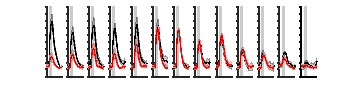

%print(gcf,'-dpdf')

% errorbar plot
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon0db(i,:)-min(avgCon0db(i,:))+0.025,stdCon0db(i,:));
    c.mainLine.LineWidth = 1;
    hold on
    c1 = shadedErrorBar(time,avgcko0db(i,:)-min(avgcko0db(i,:))+0.025,stdcko0db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    ylim([0 0.2])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.65 0.9])

%print(gcf,'-dpdf')


% get gain - 0 db

for i = 1:13
    cko0dbMax(i,:) = [max([cx261cko0db.avgRIC(i,5:20)]),max([cx262cko0db.avgLIC(i,5:20)]),max([cx263cko0db.avgLIC(i,5:20)]),max([cx264cko0db.avgLIC(i,5:20)]),max([cx265cko0db.avgLIC(i,5:20)]),max([cx266cko0db.avgRIC(i,5:20)]),max([cx267cko0db.avgRIC(i,5:20)]),max([cx268cko0db.avgRIC(i,5:20)]),max([cx2610cko0db.avgLIC(i,5:20)]),max([cx269cko0db.avgRIC(i,5:20)])];
    con0dbMax(i,:) = [max([con1db0.avgRIC(i,5:20)]),max([con2db0.avgRIC(i,5:20)]),max([con3db0.avgRIC(i,5:20)]),max([con4db0.avgRIC(i,5:20)]),max([con5db0.avgRIC(i,5:20)]),max([con6db0.avgRIC(i,5:20)]),max([con7db0.avgLIC(i,5:20)])];
end
meancko0Gain = mean([cko0dbMax],2);
stdcko0Gain = std(cko0dbMax,1,2)/sqrt(10);
meancon0Gain = mean([con0dbMax],2);
stdcon0Gain = std(con0dbMax,1,2)/sqrt(7);



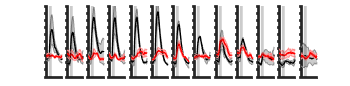

% 10 dB atten

con3db10 = load('339_5_10dB.mat');
con4db10 = load('339_6_10dB.mat'); % high spontaneous activity
con5db10 = load('342_2_10dB.mat');

cx261cko10db = load('344_1_10dB_R.mat'); % played to R ear 
cx262cko10db = load('344_2_10dB.mat'); % played to R ear
%cx263cko0db = load('347_1_10dB.mat'); % played to R ear
cx264cko10db = load('350_2_10dB.mat'); % played to R ear
cx265cko10db = load('452_3_10dB.mat'); % played to R ear

time = [1:1:length(cx261cko10db.avgLIC)];


for i = 1:16
    avgCon10db(i,:) = mean([con3db10.avgRIC(i,:);con4db10.avgRIC(i,:);con5db10.avgRIC(i,:)],1);
    stdCon10db(i,:) = std([con3db10.avgRIC(i,:);con4db10.avgRIC(i,:);con5db10.avgRIC(i,:)],1);
end

for i = 1:16
    avgcko10db(i,:) = mean([cx261cko10db.avgLIC(i,:);cx262cko10db.avgLIC(i,:);cx264cko10db.avgLIC(i,:);cx265cko10db.avgLIC(i,1:56);],1);
    stdcko10db(i,:) = std([cx261cko10db.avgLIC(i,:);cx262cko10db.avgLIC(i,:);cx264cko10db.avgLIC(i,:);cx265cko10db.avgLIC(i,1:56);],1)/sqrt(4);
end

% errorbar plot
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon10db(i,:),stdCon10db(i,:));
    c.mainLine.LineWidth = 1;
    hold on
    c1 = shadedErrorBar(time,avgcko10db(i,:),stdcko10db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    ylim([0 0.2])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.65 0.9])

%print(gcf,'-dpdf')

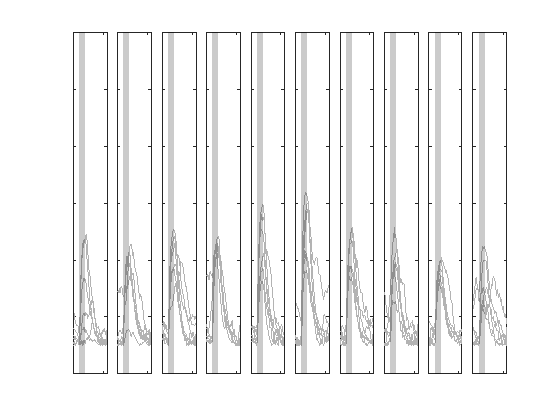

% 20 dB attenuation

% played to L ear unless otherwise noted

cx261cko20db = load('299_3_20dB.mat');
cx262cko20db = load('344_1_20dB.mat');
cx263cko20db = load('344_2_20dB.mat');
cx264cko20db = load('347_1_20dB.mat');
cx265cko20db = load('350_2_20dB.mat');
cx266cko20db = load('386_3_20dB.mat');
cx267cko20db = load('386_4_20dB.mat');
cx268cko20db = load('412_2_20dB.mat');
cx269cko20db = load('451_2_20dB.mat');
cx2610cko20db = load('452_3_20dB.mat');

con1db20 = load('308_1_20dB.mat'); % very low amplitude
con2db20 = load('327_1_20dBmoco.mat');
con3db20 = load('339_5_20dB.mat');
con4db20 = load('339_6_20dB.mat'); % high spontaneous activity
con5db20 = load('342_2_20dB.mat');
con6db20 = load('308_3_20dB.mat'); % low amp

time = [1:1:length(cx261cko0db.avgLIC)];

for i = 1:16
    avgcko20db(i,:) = mean([cx261cko20db.avgRIC(i,:);cx262cko20db.avgLIC(i,:);cx263cko20db.avgLIC(i,:);cx264cko20db.avgLIC(i,:);cx265cko20db.avgLIC(i,:);cx266cko20db.avgRIC(i,1:56);cx267cko20db.avgRIC(i,1:56);cx268cko20db.avgRIC(i,1:56);cx269cko20db.avgRIC(i,1:56);cx2610cko20db.avgLIC(i,1:56)],1);
    stdcko20db(i,:) = std([cx261cko20db.avgRIC(i,:);cx262cko20db.avgLIC(i,:);cx263cko20db.avgLIC(i,:);cx264cko20db.avgLIC(i,:);cx265cko20db.avgLIC(i,:);cx266cko20db.avgRIC(i,1:56);cx267cko20db.avgRIC(i,1:56);cx268cko20db.avgRIC(i,1:56);cx269cko20db.avgRIC(i,1:56);cx2610cko20db.avgLIC(i,1:56)],1)/sqrt(10);
end

for i = 1:16
    avgCon20db(i,:) = mean([con1db20.avgRIC(i,:);con2db20.avgRIC(i,:);con3db20.avgRIC(i,:);con4db20.avgRIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:)],1);
    stdCon20db(i,:) = std([con1db20.avgRIC(i,:);con2db20.avgRIC(i,:);con3db20.avgRIC(i,:);con4db20.avgRIC(i,:);con5db20.avgRIC(i,:);con6db20.avgRIC(i,:)],1)/sqrt(6);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:10
    subplot(1,10,i);
    plot(con1db20.avgRIC(i,:)-min(con1db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    hold on
    plot(con2db20.avgRIC(i,:)-min(con2db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con3db20.avgRIC(i,:)-min(con3db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con4db20.avgRIC(i,:)-min(con4db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con5db20.avgRIC(i,:)-min(con5db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con6db20.avgRIC(i,:)-min(con6db20.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
        patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end

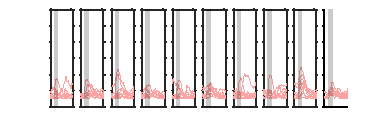

%figQuality(gcf,gca,[4 1.25])
%print(gcf,'-dpdf')
figure
for i = 1:10
    subplot(1,10,i);
    %plot(time,avgCon0db(i,:),'k','LineWidth',1);
    plot(time,cx261cko20db.avgRIC(i,:)-min(cx261cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    hold on
    plot(time,cx262cko20db.avgLIC(i,:)-min(cx262cko20db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx263cko20db.avgLIC(i,:)-min(cx263cko20db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx264cko20db.avgLIC(i,:)-min(cx264cko20db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx265cko20db.avgLIC(i,:)-min(cx265cko20db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx266cko20db.avgRIC(i,1:56)-min(cx266cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx267cko20db.avgRIC(i,1:56)-min(cx267cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx268cko20db.avgRIC(i,1:56)-min(cx268cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx269cko20db.avgRIC(i,1:56)-min(cx269cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx2610cko20db.avgLIC(i,1:56)-min(cx2610cko20db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

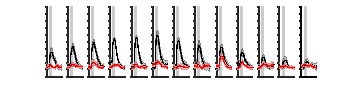

%print(gcf,'-dpdf')


% shaded error
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon20db(i,:)-min(avgCon20db(i,:))+0.025,stdCon20db(i,:));
    c.mainLine.LineWidth = 1;
    hold on
    c1 = shadedErrorBar(time,avgcko20db(i,:)-min(avgcko20db(i,:))+0.025,stdcko20db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    ylim([0 0.2])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.65 0.9])

%print(gcf,'-dpdf')

% 20 dB gain

for i = 1:13
    cko20dbMax(i,:) = [max([cx261cko20db.avgRIC(i,5:20)]),max([cx262cko20db.avgLIC(i,5:20)]),max([cx263cko20db.avgLIC(i,5:20)]),max([cx264cko20db.avgLIC(i,5:20)]),max([cx265cko20db.avgLIC(i,5:20)]),max([cx266cko20db.avgRIC(i,5:20)]),max([cx267cko20db.avgRIC(i,5:20)]),max([cx268cko20db.avgRIC(i,5:20)]),max([cx2610cko20db.avgLIC(i,5:20)]),max([cx269cko20db.avgRIC(i,5:20)])];
    con20dbMax(i,:) = [max([con1db20.avgRIC(i,5:20)]),max([con2db20.avgRIC(i,5:20)]),max([con3db20.avgRIC(i,5:20)]),max([con4db20.avgRIC(i,5:20)]),max([con5db20.avgRIC(i,5:20)]),max([con6db20.avgRIC(i,5:20)])];
end
meancko20Gain = mean([cko20dbMax],2);
stdcko20Gain = std(cko20dbMax,1,2)/sqrt(10);
meancon20Gain = mean([con20dbMax],2);
stdcon20Gain = std(con20dbMax,1,2)/sqrt(6);      



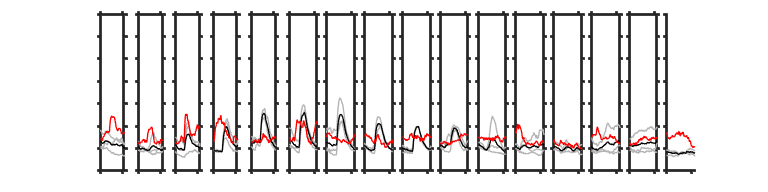

% 30 db atten

% played to L ear unless otherwise noted

cx261cko30db = load('299_3_30dB.mat');


con3db30 = load('339_5_30dB.mat');
con4db30 = load('339_6_30dB.mat'); % high spontaneous activity
con5db30 = load('342_2_30dB.mat');

time = [1:1:length(cx261cko0db.avgLIC)];

%for i = 1:16
 %   avgcko0db(i,:) = mean([cx261cko0db.avgRIC],1);
 %   stdcko0db(i,:) = std([cx261cko0db.avgRIC],1);
%end

for i = 1:16
    avgCon30db(i,:) = mean([con3db30.avgRIC(i,:);con4db30.avgRIC(i,:);con5db30.avgRIC(i,:)],1);
    stdCon30db(i,:) = std([con3db30.avgRIC(i,:);con4db30.avgRIC(i,:);con5db30.avgRIC(i,:)],1);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:16
    subplot(1,16,i);
    plot(con3db30.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    hold on
    plot(con4db30.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    plot(con5db30.avgRIC(i,:),'Color',l_grey,'LineWidth',1)
    plot(time,avgCon30db(i,:),'k','LineWidth',1);
    plot(time,cx261cko30db.avgRIC(i,:),'r','LineWidth',1)
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 2])

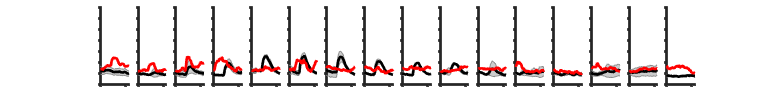


figure
for i = 1:16
    subplot(1,16,i);
    c = shadedErrorBar(time,avgCon30db(i,:),stdCon30db(i,:));
    c.mainLine.LineWidth = 2;
    hold on
    plot(time,cx261cko30db.avgRIC(i,:),'r','LineWidth',2)
    %c1 = shadedErrorBar(time,avgcko0db(i,:),stdcko0db(i,:),'lineprops','r');
    %c1.mainLine.LineWidth = 2;
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 1])

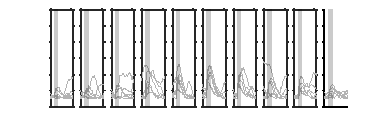

% 40 dB 
% played to L ear unless otherwise noted

cx261cko40db = load('299_3_40dB.mat');
cx262cko40db = load('344_1_40dB.mat');
cx263cko40db = load('344_2_40dB.mat');
cx264cko40db = load('347_1_40dB.mat');
cx265cko40db = load('350_2_40dB.mat');
cx266cko40db = load('386_3_40dB.mat');
cx267cko40db = load('386_4_40dB.mat');
cx268cko40db = load('412_2_40dB.mat');
cx269cko40db = load('452_3_40dB.mat');

con1db40 = load('308_1_40dB.mat'); % very low amplitude
con2db40 = load('327_1_40dBmoco.mat');
con3db40 = load('339_5_40dB.mat');
con4db40 = load('339_6_40dB.mat'); % high spontaneous activity
con5db40 = load('342_2_40dB.mat');
con6db40 = load('308_3_40dB.mat'); % low amp

time = [1:1:length(cx261cko40db.avgLIC)];

for i = 1:16
    avgcko40db(i,:) = mean([cx261cko40db.avgRIC(i,:);cx262cko40db.avgLIC(i,:);cx263cko40db.avgRIC(i,:);cx264cko40db.avgLIC(i,:);cx265cko40db.avgLIC(i,:);cx266cko40db.avgRIC(i,1:56);cx267cko40db.avgRIC(i,1:56);cx268cko40db.avgRIC(i,1:56);cx269cko40db.avgLIC(i,1:56)],1);
    stdcko40db(i,:) = std([cx261cko40db.avgRIC(i,:);cx262cko40db.avgLIC(i,:);cx263cko40db.avgRIC(i,:);cx264cko40db.avgLIC(i,:);cx265cko40db.avgLIC(i,:);cx266cko40db.avgRIC(i,1:56);cx267cko40db.avgRIC(i,1:56);cx268cko40db.avgRIC(i,1:56);cx269cko40db.avgLIC(i,1:56)],1)/sqrt(9);
end

for i = 1:16
    avgCon40db(i,:) = mean([con1db40.avgRIC(i,:);con2db40.avgRIC(i,:);con3db40.avgRIC(i,:);con4db40.avgRIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:)],1);
    stdCon40db(i,:) = std([con1db40.avgRIC(i,:);con2db40.avgRIC(i,:);con3db40.avgRIC(i,:);con4db40.avgRIC(i,:);con5db40.avgRIC(i,:);con6db40.avgRIC(i,:)],1)/sqrt(6);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:10
    subplot(1,10,i);
    plot(con1db40.avgRIC(i,:)-min(con1db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    hold on
    plot(con2db40.avgRIC(i,:)-min(con2db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con3db40.avgRIC(i,:)-min(con3db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con4db40.avgRIC(i,:)-min(con4db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con5db40.avgRIC(i,:)-min(con5db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con6db40.avgRIC(i,:)-min(con6db40.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
        patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

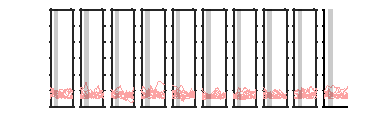

%print(gcf,'-dpdf')
figure
for i = 1:10
    subplot(1,10,i);
    %plot(time,avgCon0db(i,:),'k','LineWidth',1);
    plot(time,cx261cko40db.avgRIC(i,:)-min(cx261cko20db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    hold on
    plot(time,cx262cko40db.avgLIC(i,:)-min(cx262cko40db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx263cko40db.avgLIC(i,:)-min(cx263cko40db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx264cko40db.avgLIC(i,:)-min(cx264cko40db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx265cko40db.avgLIC(i,:)-min(cx265cko40db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx266cko40db.avgRIC(i,1:56)-min(cx266cko40db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx267cko40db.avgRIC(i,1:56)-min(cx267cko40db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx268cko40db.avgRIC(i,1:56)-min(cx268cko40db.avgRIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    plot(time,cx269cko40db.avgLIC(i,1:56)-min(cx269cko40db.avgLIC(i,:))+0.025,'color',l_red,'LineWidth',0.5)
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

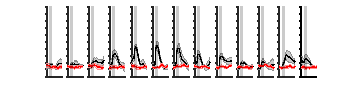

%print(gcf,'-dpdf')

% shaded error
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon40db(i,:)-min(avgCon40db(i,:))+0.025,stdCon40db(i,:));
    c.mainLine.LineWidth = 1;
    hold on
    c1 = shadedErrorBar(time,avgcko40db(i,:)-min(avgcko40db(i,:))+0.025,stdcko40db(i,:),'lineprops','r');
    c1.mainLine.LineWidth = 1;
    ylim([0 0.2])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.65 0.9])

%print(gcf,'-dpdf')


% 40 dB gain
for i = 1:13
    cko40dbMax(i,:) = [max([cx261cko40db.avgRIC(i,5:20)]),max([cx262cko40db.avgLIC(i,5:20)]),max([cx263cko40db.avgLIC(i,5:20)]),max([cx264cko40db.avgLIC(i,5:20)]),max([cx265cko40db.avgLIC(i,5:20)]),max([cx266cko40db.avgRIC(i,5:20)]),max([cx267cko40db.avgRIC(i,5:20)]),max([cx268cko40db.avgRIC(i,5:20)]),max([cx269cko40db.avgLIC(i,5:20)])];
    con40dbMax(i,:) = [max([con1db40.avgRIC(i,5:20)]),max([con2db40.avgRIC(i,5:20)]),max([con3db40.avgRIC(i,5:20)]),max([con4db40.avgRIC(i,5:20)]),max([con5db40.avgRIC(i,5:20)]),max([con6db40.avgRIC(i,5:20)])];
end
meancko40Gain = mean([cko40dbMax],2);
stdcko40Gain = std(cko40dbMax,1,2)/sqrt(9);
meancon40Gain = mean([con40dbMax],2);
stdcon40Gain = std(con40dbMax,1,2)/sqrt(6);      


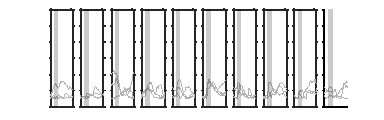

% 60 dB attenuation - no cKO

con1db60 = load('308_1_60dB.mat'); % check these for delay
con3db60 = load('339_5_60dB.mat');
con6db60 = load('308_3_60dB.mat');
con4db60 = load('339_6_60dB.mat');

time = [1:1:length(con1db60.avgLIC)];

for i = 1:16
    avgCon60db(i,:) = mean([con1db60.avgRIC(i,:);con3db60.avgRIC(i,:);con4db60.avgRIC(i,:);con6db60.avgRIC(i,:)],1);
    stdCon60db(i,:) = std([con1db60.avgRIC(i,:);con3db60.avgRIC(i,:);con4db60.avgRIC(i,:);con6db60.avgRIC(i,:)],1)/sqrt(4);
end

l_grey = [0.7 0.7 0.7];
l_red = [252/255 163/255 163/255];
figure
for i = 1:10
    subplot(1,10,i);
    plot(con1db60.avgRIC(i,:)-min(con1db60.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    hold on
    plot(con3db60.avgRIC(i,:)-min(con3db60.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
   % plot(con4db60.avgRIC(i,:)-min(con4db60.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
    plot(con6db60.avgRIC(i,:)-min(con6db60.avgRIC(i,:))+0.025,'Color',l_grey,'LineWidth',0.5)
        patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
    ylim([0 0.3])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[4 1.25])

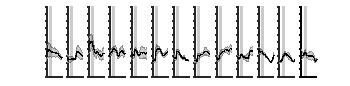

%print(gcf,'-dpdf')



% shaded error
figure
for i = 1:13
    subplot(1,13,i);
    c = shadedErrorBar(time,avgCon60db(i,:),stdCon60db(i,:));
    c.mainLine.LineWidth = 1;
    hold on
    %c1 = shadedErrorBar(time,avgcko40db(i,:)-0.025,stdcko40db(i,:),'lineprops','r');
   % c1.mainLine.LineWidth = 1;
    ylim([0 0.2])
    yticklabels([]);
    xticklabels([]);
    patch([10 10 20 20], [1 -6 -6 1],'k','EdgeColor','none','FaceAlpha',0.2);
end
figQuality(gcf,gca,[3.65 0.9])

%print(gcf,'-dpdf')

% 60 dB gain
for i = 1:13
    con60dbMax(i,:) = [max([con1db60.avgRIC(i,5:20)]),max([con3db60.avgRIC(i,5:20)]),max([con4db60.avgRIC(i,5:20)]),max([con6db60.avgRIC(i,5:20)])];
end
meancon60Gain = mean([con60dbMax],2);
stdcon60Gain = std(con60dbMax,1,2)/sqrt(4);   


% plot gain 

i = 4; % 9.5 kHz
x = [4:-1:1];

c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko40Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko40Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


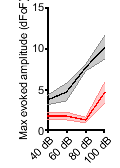

c1.mainLine.LineWidth = 1;
hold on
ylim([0 15])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])
print(gcf,'-dpdf')

i = 10; % 15 kHz 
figure
c = shadedErrorBar(x,[meancon0Gain(i),meancon20Gain(i),meancon40Gain(i),meancon60Gain(i)]*100-5,[stdcon0Gain(i),stdcon20Gain(i),stdcon40Gain(i),stdcon60Gain(i)]*100)

c = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


c.mainLine.LineWidth = 1;
hold on
c1 = shadedErrorBar(x,[meancko0Gain(i),meancko20Gain(i),meancko40Gain(i),meancko40Gain(i)]*100-5,[stdcko0Gain(i),stdcko20Gain(i),stdcko40Gain(i),stdcko40Gain(i)]*100,'lineprops','r')

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


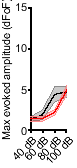

c1.mainLine.LineWidth = 1;
hold on
ylim([0 15])
xticks([1 2 3 4])
xticklabels({'40 dB','60 dB','80 dB','100 dB'})
xtickangle([45])
xlim([1 4])
ylabel('Max evoked amplitude (dFoF)')
figQuality(gcf,gca,[0.8 1.75])

%print(gcf,'-dpdf')

gainMatxCon = [con0dbMax(i,:);[con20dbMax(i,:) NaN];[con40dbMax(i,:) NaN];];
gainMatxcko = [cko0dbMax(i,:);cko20dbMax(i,:);[cko40dbMax(i,:) NaN];];




% linear mixed model 
genoBasecon = {'con','con','con'};
genoBasecko = {'cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M2','M2','M2','M3','M3','M3','M4','M4','M4','M5','M5','M5','M6','M6','M6','M7','M7','M7'};
mousecko = {'M8','M8','M8','M9','M9','M9','M10','M10','M10','M11','M11','M11','M12','M12','M12','M13','M13','M13','M14','M14','M14','M15','M15','M15','M16','M16','M16','M17','M17','M17'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [gainMatxCon(:,1)',gainMatxCon(:,2)',gainMatxCon(:,3)',gainMatxCon(:,4)',gainMatxCon(:,5)',gainMatxCon(:,6)',gainMatxCon(:,7)',gainMatxcko(:,1)',gainMatxcko(:,2)',gainMatxcko(:,3)',gainMatxcko(:,4)',gainMatxcko(:,5)',gainMatxcko(:,6)',gainMatxcko(:,7)',gainMatxcko(:,8)',gainMatxcko(:,9)',gainMatxcko(:,10)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 51×4 table
    Genotype    Mouse     Location       BW   
    ________    ______    ________    ________

    {'con'}     {'M1'}     {'1'}       0.13625
    {'con'}     {'M1'}     {'2'}      0.093698
    {'con'}     {'M1'}     {'3'}      0.085543
    {'con'}     {'M2'}     {'1'}       0.12366
    {'con'}     {'M2'}     {'2'}       0.10293
    {'con'}     {'M2'}     {'3'}       0.14664
    {'con'}     {'M3'}     {'1'}       0.12055
    {'con'}     {'M3'}     {'2'}       0.12357
    {'con'}     {'M3'}     {'3'}       0.10384
    {'con'}     {'M4'}     {'1'}      0.082877
    {'con'}     {'M4'}     {'2'}       0.18318
    {'con'}     {'M4'}     {'3'}      0.076293
    {'con'}     {'M5'}     {'1'}       0.11931
    {'con'}     {'M5'}     {'2'}       0.11072
    {'con'}     {'M5'}     {'3'}      0.090117
    {'con'}     {'M6'}     {'1'}      0.099804


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)')  

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations              48
    Fixed effects coefficients           2
    Random effects coefficients         20
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -181.89    -172.53    95.945           -191.89 

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF    pValue        Lower        Upper    
    {'(Intercept)' }          0.10617     0.011872     8.9422    46    1.2578e-11     0.082268      0.13006
    {'Genotype_cko'}        -0.024346    0.0097923    -2.4862    46      0.016604    -0.044057    -0.004635

Random effects covariance parameters (95% CIs):
Group: Location (3 Levels)
    Name1                  Name2  

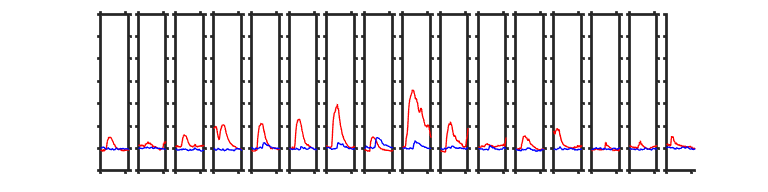

% sound evoked responses following ketamine-xylazine dose

cx26cko0dbPre = load('350_2_0dB.mat'); % played to R ear
cx26cko0dbPost = load('350_2_0dBketamine.mat'); % played to R ear
figure
for i = 1:16
    subplot(1,16,i);
    plot(cx26cko0dbPre.avgLIC(i,:),'r','LineWidth',1)
    hold on
    plot(cx26cko0dbPost.avgLIC(i,:),'b','LineWidth',1)
    ylim([0 0.35])
    yticklabels([]);
    xticklabels([]);
end
figQuality(gcf,gca,[8 2])

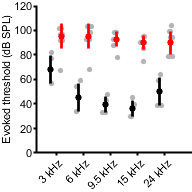

% Threshold analysis widefield

noAtten = [102 105 107 103 104 103 102 100 110 109 110 110 108];
Atten10 = noAtten - 10;
Atten20 = noAtten - 20;
Atten30 = noAtten - 30;
Atten40 = noAtten - 40;
Atten50 = noAtten - 50;
Atten60 = noAtten - 60;
Atten70 = noAtten - 70;

attenMatx = [noAtten;Atten10;Atten20;Atten30;Atten40;Atten50;Atten60;Atten70];

% cko thresholds - 
cko1db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; %299_3
cko1db20 = [1 1 1 1 1 1 1 1 1 0 1 0 0]; 
cko1db30 = [1 1 1 1 0 0 0 0 0 0 0 0 0]; 
cko1db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko2db0 = [0 0 0 0 0 1 1 1 1 1 0 0 0]; %344_1
cko2db10 = [0 0 0 0 0 0 0 0 1 1 0 0 0];
cko2db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko2db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko3db0 = [0 0 0 0 0 1 1 1 1 1 1 0 0]; % 344_2
cko3db10 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko3db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko3db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko4db0 = [0 0 0 0 0 1 1 1 1 1 1 0 0]; % 347_1
cko4db20 = [0 0 0 0 0 0 0 0 1 1 0 0 0];
cko4db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko5db0 = [1 1 1 1 1 1 1 1 1 1 0 1 0]; %350_2
cko5db10 = [0 0 0 0 0 0 1 0 1 1 0 0 0];
cko5db20 = [0 0 0 0 0 0 0 0 1 0 0 0 0];
cko5db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko6db0 = [1 1 1 1 1 1 1 1 1 1 0 0 0]; % 386_3
cko6db20 = [0 0 0 0 0 0 0 0 1 1 0 0 0];
cko6db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko7db0 = [0 1 1 1 1 1 1 1 1 1 1 1 0]; % 386_4
cko7db20 = [0 0 0 0 0 0 0 0 1 1 0 0 0];
cko7db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko8db0 = [1 0 0 1 1 1 1 1 1 1 1 1 0]; % 412_2
cko8db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko8db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

cko9db0 = [0 0 0 0 1 1 1 1 1 1 1 1 0]; % 451-2
cko9db10 = [0 0 0 0 0 0 0 1 1 1 1 0 0]; 
cko9db20 = [0 0 0 0 0 0 0 0 0 0 0 0 0];
cko9db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0]; 

cko10db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; % 452-3
cko10db10 = [0 0 0 0 1 1 1 0 1 1 1 1 0];
cko10db20 = [0 0 0 0 0 0 0 0 1 1 0 0 0];
cko10db40 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

% controls 
con1db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %308_1 flfl
con1db20 = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1db40 = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con1db60 = [0 0 0 0 1 1 1 1 1 1 1 1 1];

con2db0 = [1 1 1 1 1 1 1 1 1 1 1 1 1]; %308_3 flfl
con2db20 = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con2db40 = [1 1 1 1 1 1 1 1 1 1 1 1 1];
con2db60 = [0 0 0 1 1 1 1 1 1 1 1 1 0];

con3db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; % 339_5
con3db10 = [1 1 1 1 1 1 1 1 1 1 1 0 0];
con3db20 = [1 1 1 1 1 1 1 1 1 1 1 0 0];
con3db30 = [0 0 1 1 1 1 1 1 1 1 0 0 0];
con3db40 = [0 0 0 1 1 1 1 1 1 1 0 0 0];
con3db50 = [0 0 0 0 0 1 1 1 1 0 0 0 0];
con3db60 = [0 0 0 0 0 0 0 0 0 0 0 0 0];

con4db0 = [1 1 1 1 1 1 1 1 1 1 1 1 0]; %342_2
con4db10 = [1 1 1 1 1 1 1 1 1 1 1 0 0];
con4db20 = [0 1 1 1 1 1 1 1 1 1 1 0 0];
con4db30 = [0 0 0 1 1 1 1 1 1 1 0 0 0];
con4db40 = [0 0 0 0 1 1 1 1 1 1 0 0 0];
con4db50 = [0 0 0 0 1 1 1 1 1 1 0 0 0];

% calculate threshold
threshCko1 = getThresh(cko1db0,cko1db20,cko1db40);
threshCko1(1:4) = threshCko1(1:4)-5;
threshCko1(5:9) = threshCko1(5:9)+5;
threshCko2 = getThresh(cko2db0,cko2db20,cko2db40);
threshCko2(9:10) = threshCko2(9:10)-5;
threshCko2(6:8) = threshCko2(6:8)+5;
threshCko3 = getThresh(cko3db0,cko3db20,cko3db40);
threshCko3(6:11) = threshCko3(6:11)+5;
threshCko4 = getThresh(cko4db0,cko4db20,cko4db40);
threshCko5 = getThresh(cko5db0,cko5db20,cko5db40);
threshCko5(1:6) = threshCko5(1:6) + 5;
threshCko5(7) = threshCko5(7) - 5;
threshCko5(8) = threshCko5(8) + 5;
threshCko5(10) = threshCko5(10) - 5;
threshCko6 = getThresh(cko6db0,cko6db20,cko6db40);
threshCko7 = getThresh(cko7db0,cko7db20,cko7db40);
threshCko8 = getThresh(cko8db0,cko8db20,cko8db40);
threshCko9 = getThresh(cko9db0,cko9db20,cko9db40);
threshCko9(5:7) = threshCko9(5:7) + 5;
threshCko9(8:11) = threshCko9(8:11) - 5;
threshCko10 = getThresh(cko10db0,cko10db20,cko10db40);
threshCko10(1:4) = threshCko10(1:4)+5;
threshCko10(5:7) = threshCko10(5:7)-5;
threshCko10(8) = threshCko10(8)+5;
threshCko10(11:12) = threshCko10(11:12)-5;
ckoMeanMatx = [threshCko1(1:10)',threshCko2(1:10)',threshCko3(1:10)',threshCko4(1:10)',threshCko5(1:10)',threshCko6(1:10)',threshCko7(1:10)',threshCko8(1:10)',threshCko9(1:10)',threshCko10(1:10)'];
cko3 = [threshCko1(1),threshCko2(1),threshCko3(1),threshCko4(1),threshCko5(1),threshCko6(1),threshCko7(1),threshCko8(1),threshCko9(1),threshCko10(1)];
cko6 = [threshCko1(4),threshCko2(4),threshCko3(4),threshCko4(4),threshCko5(4),threshCko6(4),threshCko7(4),threshCko8(4),threshCko9(4),threshCko10(4)];
cko9_5 = [threshCko1(6),threshCko2(6),threshCko3(6),threshCko4(6),threshCko5(6),threshCko6(6),threshCko7(6),threshCko8(6),threshCko9(6),threshCko10(6)];
cko12 = [threshCko1(8),threshCko2(8),threshCko3(8),threshCko4(8),threshCko5(8),threshCko6(8),threshCko7(8),threshCko8(8),threshCko9(8),threshCko10(8)];
cko24 = [threshCko1(10),threshCko2(10),threshCko3(10),threshCko4(10),threshCko5(10),threshCko6(10),threshCko7(10),threshCko8(10),threshCko9(10),threshCko10(10)];
%cko3 = [threshCko1(1),threshCko2(1),threshCko3(1),threshCko4(1),threshCko5(1),threshCko6(1),threshCko7(1),threshCko8(1),threshCko9(1),threshCko10(1)];

ckoMean = mean([threshCko1;threshCko2;threshCko3;threshCko4;threshCko5;threshCko6;threshCko7;threshCko8;threshCko9;threshCko10],1);
ckoSTD = std([threshCko1;threshCko2;threshCko3;threshCko4;threshCko5;threshCko6;threshCko7;threshCko8;threshCko9;threshCko10],1);

threshcon1 = getThresh4files(con1db0,con1db20,con1db40,con1db60);
threshcon2 = getThresh4files(con2db0,con2db20,con2db40,con2db60);
threshcon3 = getThresh4files(con3db0,con3db20,con3db40,con3db60);
threshcon3(1:2) = threshcon3(1:2)+5;
threshcon3(10:11) = threshcon3(10:11)+5;
threshcon3(4:5) = threshcon3(4:5)+5;
threshcon3(6:9) = threshcon3(6:9)-5;
threshcon4 = getThresh(con4db0,con4db20,con4db40);
threshcon4(3) = threshcon4(3)+5;
threshcon4(11) = threshcon4(11)+5;
threshcon4(5:10) = threshcon3(5:10)-5;

conMean = mean([threshcon1;threshcon2;threshcon3;threshcon4]); 
conSTD = std([threshcon1;threshcon2;threshcon3;threshcon4]); 
conditions = {'3 kHz','6 kHz','9.5 kHz','15 kHz','24 kHz'};
con3 = [threshcon1(3),threshcon2(3),threshcon3(3),threshcon4(3)];
con6 = [threshcon1(5),threshcon2(5),threshcon3(5),threshcon4(5)];
con9_5 = [threshcon1(6),threshcon2(6),threshcon3(6),threshcon4(6)];
con12 = [threshcon1(8),threshcon2(8),threshcon3(8),threshcon4(8)];
con24 = [threshcon1(10),threshcon2(10),threshcon3(10),threshcon4(10)];
conMeanMatx = [threshcon1(1:10)',threshcon2(1:10)',threshcon3(1:10)',threshcon4(1:10)'];
ylbl = 'Evoked threshold (dB SPL)';
dim = [2 2];
markSz = [17 17];
color1 = 'k';
color2 = 'r';
compare5offsetM(con3,con6,con9_5,con12,con24,conditions,ylbl,dim,markSz,color1,color1)
compare5offsetP(cko3,cko6,cko9_5,cko12,cko24,conditions,ylbl,dim,markSz,color2,color1)
ylim([0 120])


figure;
freq = [1:1:13]

freq =      1     2     3     4     5     6     7     8     9    10    11    12    13


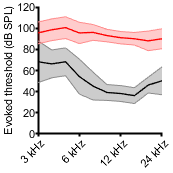

c = shadedErrorBar(freq,conMean,conSTD);
c.mainLine.LineWidth = 1;
c = shadedErrorBar(freq,ckoMean,ckoSTD,'lineprops','r');
c.mainLine.LineWidth = 1;
ylim([0 120])
xlim([1 10])
ylabel(ylbl,'FontSize',8);
xticks([1 4 7 10]);
xticklabels({'3 kHz','6 kHz','12 kHz','24 kHz'})
xtickangle([45])
figQuality(gcf,gca,[1.8 1.8])

%print(gcf,'-dpdf')

% linear mixed model 
genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4'};
mousecko = {'M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6','M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13','M15','M15','M15','M15','M15','M15','M15','M15','M15','M15','M16','M16','M16','M16','M16','M16','M16','M16','M16','M16'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)',ckoMeanMatx(:,6)',ckoMeanMatx(:,7)',ckoMeanMatx(:,8)',ckoMeanMatx(:,9)',ckoMeanMatx(:,10)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 140×4 table
    Genotype    Mouse     Location    BW
    ________    ______    ________    __

    {'con'}     {'M1'}     {'1' }     52
    {'con'}     {'M1'}     {'2' }     55
    {'con'}     {'M1'}     {'3' }     57
    {'con'}     {'M1'}     {'4' }     53
    {'con'}     {'M1'}     {'5' }     34
    {'con'}     {'M1'}     {'6' }     33
    {'con'}     {'M1'}     {'7' }     32
    {'con'}     {'M1'}     {'8' }     30
    {'con'}     {'M1'}     {'9' }     40
    {'con'}     {'M1'}     {'10'}     39
    {'con'}     {'M2'}     {'1' }     52
    {'con'}     {'M2'}     {'2' }     55
    {'con'}     {'M2'}     {'3' }     57
    {'con'}     {'M2'}     {'4' }     33
    {'con'}     {'M2'}     {'5' }     34
    {'con'}     {'M2'}     {'6' }     33


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')  

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations             140
    Fixed effects coefficients           2
    Random effects coefficients         24
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1014.8    1029.4    -502.39          1004.8  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF     pValue        Lower     Upper 
    {'(Intercept)' }        51.25        4.524    11.328    138    1.9221e-21    42.305    60.195
    {'Genotype_cko'}        42.55       4.9064    8.6724    138    1.0374e-14    32.849    52.251

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type           


[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =    51.2500
   42.5500


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }        51.25        4.524    11.328    16.027    4.6305e-09    41.661    60.839
    {'Genotype_cko'}        42.55       4.9064    8.6724        12    1.6305e-06     31.86     53.24


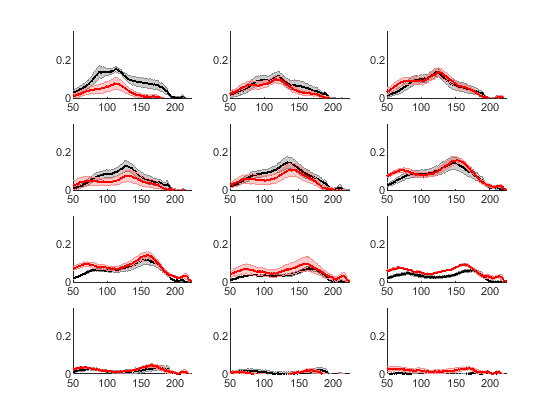

% spatial analysis, band width

cko1 = load('299_3_0dBprofile6khz');
cko2 = load('386_3_0dBprofile6khz');
cko3 = load('386_4_0dBprofile6khz'); % no 6 kHz really, very very dim
cko4 = load('452_3_0dBprofile6khz.mat'); % meh

con1 = load('308_1_0dBprofile6khz.mat');
%con2 = load('308_3_0dBprofile6khz.mat'); % inf values
con3 = load('327_1_0dBprofile6khz.mat');
con4 = load('339_5_0dBprofile6khz.mat');
con5 = load('342_2_0dBprofile6khz.mat');
con6 = load('419_3_0dBprofile6khz.mat');

% all freq
figure
cko = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    cko(i).mean = nanmean([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';],1)-0.1;
    con(i).mean = nanmean([con1.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)-0.1;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    cko(i).std = nanstd([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';],1)/sqrt(4);
    con(i).std = nanstd([con1.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)/sqrt(5);
   % tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    xlim([50 225])
end

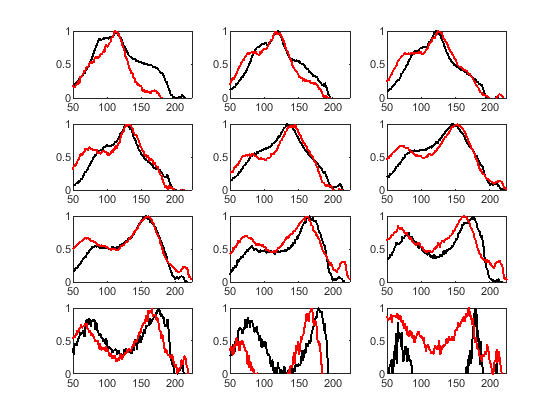


% all freq normalized

% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(51:225));
    hold on
    plot(cko(i).mean/nanmax(cko(i).mean(50:225)),'r','LineWidth',1.5)
    cko(i).norm = cko(i).mean/nanmax(cko(i).mean(50:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
   % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end


% others - not included in profile (poor)
con7 = load('350_1_0dBprofile6khz.mat');
cko5 = load('350_2_0dBprofile6khz.mat');


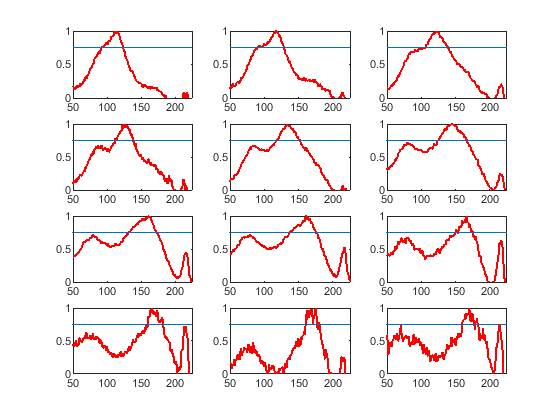

% measure bandwidth - cKO mice
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko1BW = (cko1.meanLIC(i).profileraw'-0.1)/(max(cko1.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko1BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko1bandW(i) = sum(smooth(cko1BW(90:225))> perctile)*scale;
    [cko1Peak(i) cko1PeakLoc(i)] = max(smooth(cko1.meanLIC(i).profileraw(50:225)'));
    cko1PeakLoc(i) = cko1PeakLoc(i)+49;
end

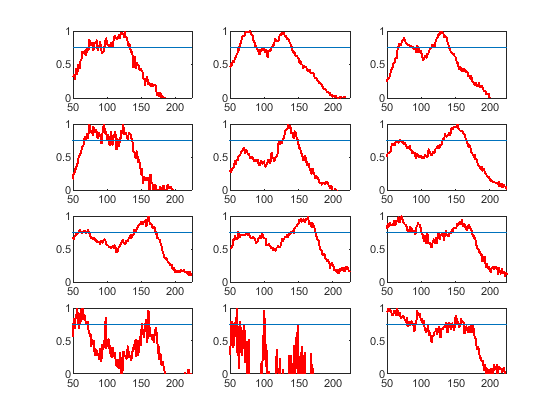

cko1PeakLoc =  cko1PeakLoc*scale;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko2BW = (cko2.meanLIC(i).profileraw'-0.1)/(max(cko2.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko2BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko2bandW(i) = sum(smooth(cko2BW(90:225))> perctile)*scale;
    [cko2Peak(i) cko2PeakLoc(i)] = max(smooth(cko2.meanLIC(i).profileraw(50:225)'));
    cko2PeakLoc(i) = cko2PeakLoc(i)+49;
end

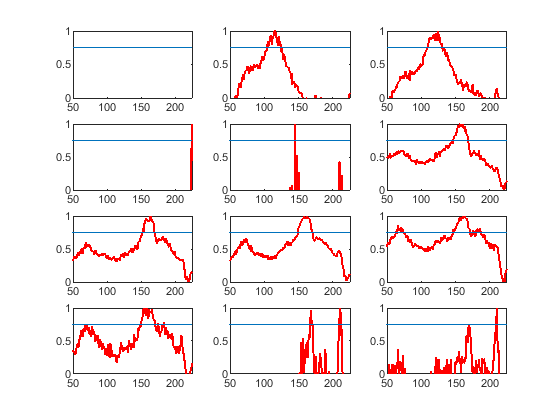

cko2PeakLoc =  cko2PeakLoc*scale;
cko2bandW(1:4) = NaN;
cko2bandW(9:10) = NaN;
cko2PeakLoc(1:2) = NaN;
cko2PeakLoc(4) = NaN;
cko2PeakLoc(9:10) = NaN;
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko3BW = (cko3.meanLIC(i).profileraw'-0.1)/(max(cko3.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko3BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko3bandW(i) = sum(smooth(cko3BW(90:225))> perctile)*scale;
    [cko3Peak(i) cko3PeakLoc(i)] = max(smooth(cko3.meanLIC(i).profileraw(50:225)'));
    cko3PeakLoc(i) = cko3PeakLoc(i)+49;
end

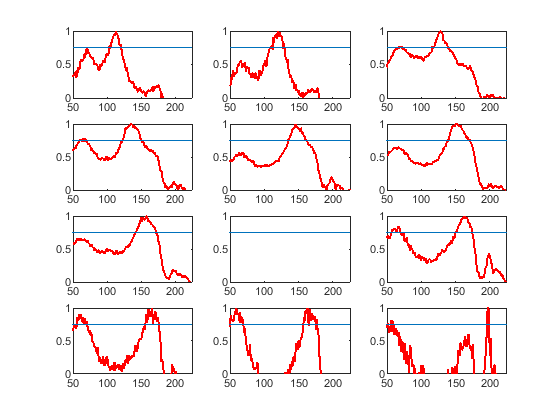

cko3PeakLoc =  cko3PeakLoc*scale;
cko3bandW(1) = NaN;
cko3bandW(4:5) = NaN;
cko3bandW(9:10) = NaN;
cko3PeakLoc(1) = NaN;
cko3PeakLoc(4:5) = NaN;
cko3PeakLoc(9:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko4BW = (cko4.meanLIC(i).profileraw'-0.1)/(max(cko4.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko4BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko4bandW(i) = sum(smooth(cko4BW(90:225))> perctile)*scale;
    [cko4Peak(i) cko4PeakLoc(i)] = max(smooth(cko4.meanLIC(i).profileraw(50:225)'));
    cko4PeakLoc(i) = cko4PeakLoc(i)+49;
end

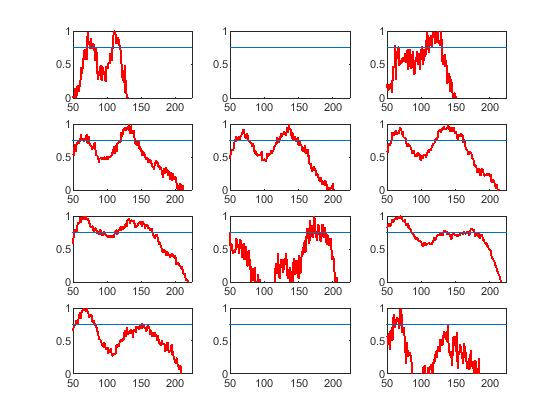

cko4PeakLoc =  cko4PeakLoc*scale;
cko4bandW(3) = NaN;
cko4bandW(8) = NaN;
cko4PeakLoc(8) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko5BW = (cko5.meanLIC(i).profileraw'-0.1)/(max(cko5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko5BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko5bandW(i) = sum(smooth(cko5BW(90:225))> perctile)*scale;
    [cko5Peak(i) cko5PeakLoc(i)] = max(smooth(cko5.meanLIC(i).profileraw(50:225)'));
    cko5PeakLoc(i) = cko5PeakLoc(i)+49;
end

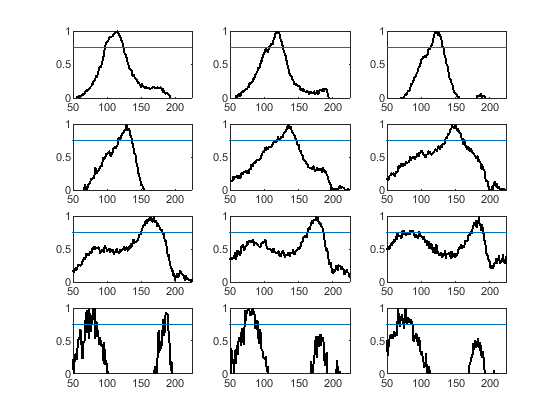

cko5PeakLoc =  cko5PeakLoc*scale;
cko5bandW(1:3) = NaN;
cko5bandW(7:10) = NaN;
cko5PeakLoc(1:3) = NaN;
cko5PeakLoc(7:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.67; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con1BW = (con1.meanLIC(i).profileraw'-0.1)/(max(con1.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con1BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con1bandW(i) = sum(smooth(con1BW(90:225))> perctile)*scale;
    [con1Peak(i) con1PeakLoc(i)] = max(smooth(con1.meanLIC(i).profileraw(50:225)'));
    con1PeakLoc(i) = con1PeakLoc(i)+49;
end

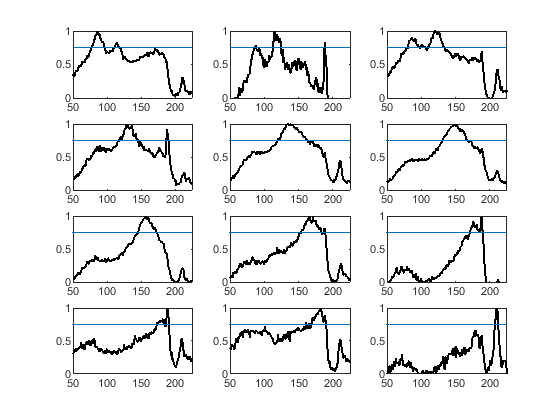

con1PeakLoc =  con1PeakLoc*scale;
con1bandW(10) = NaN;
con1PeakLoc(10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.62; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con3BW = (con3.meanLIC(i).profileraw'-0.1)/(max(con3.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con3BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con3bandW(i) = sum(smooth(con3BW(90:225))> perctile)*scale;
    [con3Peak(i) con3PeakLoc(i)] = max(smooth(con3.meanLIC(i).profileraw(50:225)'));
    con3PeakLoc(i) = con3PeakLoc(i)+49;
end

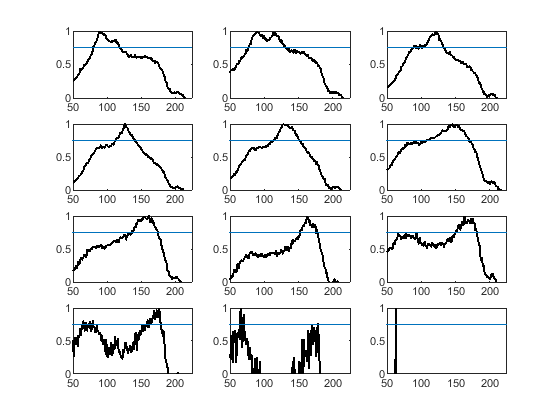

con3PeakLoc =  con3PeakLoc*scale;
con3bandW(1:4) = NaN;
con3bandW(10) = NaN;
con3PeakLoc(1) = NaN;
con3PeakLoc(9:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.65; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con4BW = (con4.meanLIC(i).profileraw'-0.1)/(max(con4.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con4BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con4bandW(i) = sum(smooth(con4BW(90:225))> perctile)*scale;
    [con4Peak(i) con4PeakLoc(i)] = max(smooth(con4.meanLIC(i).profileraw(50:225)'));
    con4PeakLoc(i) = con4PeakLoc(i)+49;
end

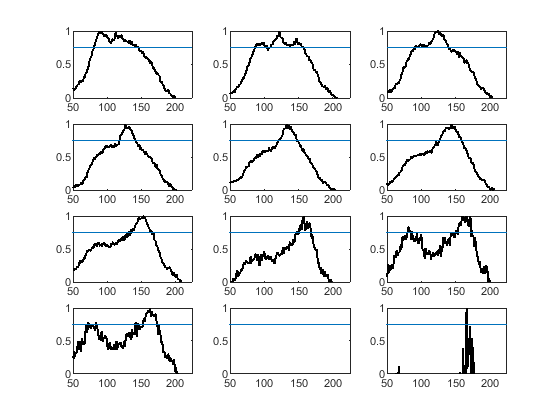

con4PeakLoc =  con4PeakLoc*scale;
con4bandW(1:2) = NaN;
con4bandW(6) = NaN;
con4bandW(10) = NaN;
con4PeakLoc(1:2) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con5BW = (con5.meanLIC(i).profileraw'-0.1)/(max(con5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con5BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con5bandW(i) = sum(smooth(con5BW(90:225))> perctile)*scale;
    [con5Peak(i) con5PeakLoc(i)] = max(smooth(con5.meanLIC(i).profileraw(50:225)'));
    con5PeakLoc(i) = con5PeakLoc(i)+49;
end

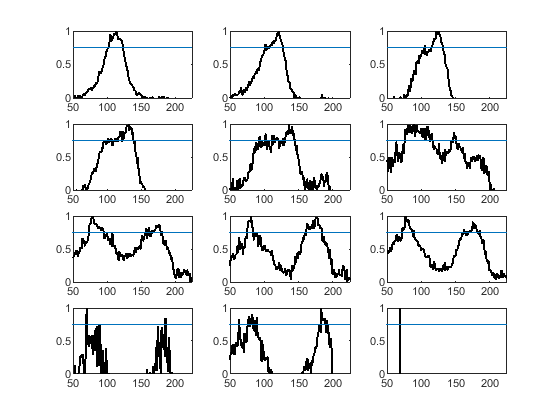

con5PeakLoc =  con5PeakLoc*scale;
con5bandW(1:3) = NaN;
con5PeakLoc(1) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con6BW = (con6.meanLIC(i).profileraw'-0.1)/(max(con6.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con6BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con6bandW(i) = sum(smooth(con6BW(90:225))> perctile)*scale;
    [con6Peak(i) con6PeakLoc(i)] = max(smooth(con6.meanLIC(i).profileraw(50:225)'));
    con6PeakLoc(i) = con6PeakLoc(i)+49;
end

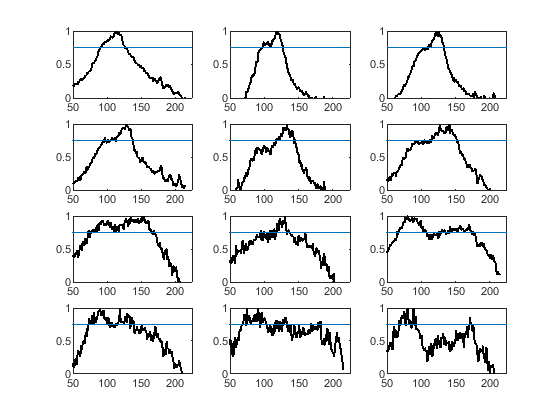

con6PeakLoc =  con6PeakLoc*scale;
con6bandW(5:7) = NaN;
con6bandW(9:10) = NaN;
con6PeakLoc(6:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con7BW = (con7.meanLIC(i).profileraw'-0.1)/(max(con7.meanLIC(i).profileraw(50:200)'-0.1));
    plot(con7BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con7bandW(i) = sum(smooth(con7BW(90:225))> perctile)*scale;
    [con7Peak(i) con7PeakLoc(i)] = max(smooth(con7.meanLIC(i).profileraw(50:225)'));
    con7PeakLoc(i) = con7PeakLoc(i)+49;
end

con7PeakLoc =  con7PeakLoc*scale;
con7bandW(7:10) = NaN;
con7PeakLoc(6:10) = NaN;


% plus smoothing, inclusion of 24 kHz
perctile = 0.75; % 80th percentile, normalized
conMeanMatx = [];
ckoMeanMatx = [];
for i = 1:10
    
    conMean(i) =nanmean([con1bandW(i),con3bandW(i),con4bandW(i),con5bandW(i),con6bandW(i),con7bandW(i)]);
    conMeanMatx = [conMeanMatx;[con1bandW(i),con3bandW(i),con4bandW(i),con5bandW(i),con6bandW(i),con7bandW(i)]];
    ckoMean(i) = nanmean([cko1bandW(i),cko2bandW(i),cko3bandW(i),cko4bandW(i),cko5bandW(i)]);
    ckoMeanMatx = [ckoMeanMatx;[cko1bandW(i),cko2bandW(i),cko3bandW(i),cko4bandW(i),cko5bandW(i)]];
    sterrConBW(i) = nanstd([con1bandW(i),con3bandW(i),con4bandW(i),con5bandW(i),con6bandW(i),con7bandW(i)])/sqrt(5);
   sterrckoBW(i) = nanstd([cko1bandW(i),cko2bandW(i),cko3bandW(i),cko4bandW(i),cko5bandW(i)])/sqrt(4);    
end
scale = 7.63; %um/pixel
figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMean,sterrConBW)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,ckoMean,sterrckoBW,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


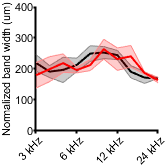

    c2.mainLine.LineWidth = 1.5;
ylim([0 400]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Normalized band width (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mousecko = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 110×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     207.09
    {'con'}     {'M1'}     {'2' }      153.4
    {'con'}     {'M1'}     {'3' }     145.73
    {'con'}     {'M1'}     {'4' }     145.73
    {'con'}     {'M1'}     {'5' }     222.43
    {'con'}     {'M1'}     {'6' }     191.75
    {'con'}     {'M1'}     {'7' }     245.44
    {'con'}     {'M1'}     {'8' }     168.74
    {'con'}     {'M1'}     {'9' }     138.06
    {'con'}     {'M1'}     {'10'}        NaN
    {'con'}     {'M2'}     {'1' }        NaN
    {'con'}     {'M2'}     {'2' }        NaN
    {'con'}     {'M2'}     {'3' }        NaN
    {'con'}     {'M2'}     {'4' }        NaN
    {'con'}     {'M2'}     {'5' }     327.66
    {'con'}     {'M2'}     {'6' }     281.94


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              68
    Fixed effects coefficients           2
    Random effects coefficients         21
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    718.26    729.2    -354.13          708.26  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF    pValue        Lower      Upper 
    {'(Intercept)' }            215     17.017      12.635    66    2.7872e-19     181.03    248.98
    {'Genotype_cko'}        -7.3127     23.004    -0.31789    66       0.75157    -53.241    38.615

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type       

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta =   215.0026
   -7.3127


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat       DF        pValue        Lower      Upper 
    {'(Intercept)' }            215     17.017      12.635    12.154    2.3667e-08     177.98    252.03
    {'Genotype_cko'}        -7.3127     23.004    -0.31789    9.3645       0.75754    -59.043    44.418



% plot profiles
i = 3; % 4.5 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
%  c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))
%  l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
%  l2_1.Color = 'r';
%  l2_1.LineStyle = ':';
%  l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])
  
 i = 7; %12  kHz
 subplot(1,3,2)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 [y1_2 x1_2] = nanmax(smooth(con(i).mean(51:225)));
 l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
 l1_2.Color = 'k';
 l1_2.LineStyle = ':'

l1_2 =   Line with properties:

              Color: [0 0 0]
          LineStyle: ':'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [156 156]
              YData: [0 0.1177]
              ZData: [1×0 double]

  Show all properties


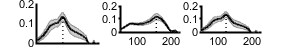

 l1_2.LineWidth = 1;
%  c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_2 x2_2] = nanmax(smooth(cko(i).mean(50:225)));
%  l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
%  l2_2.Color = 'r';
%  l2_2.LineStyle = ':';
%  l2_2.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])
  
  subplot(1,3,3)
  i = 3;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
%  c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
%  c1.mainLine.LineWidth = 1.5;
%  [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))
%  l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
%  l2_1.Color = 'r';
%  l2_1.LineStyle = ':';
%  l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])

 % print(gcf,'-dpdf')

  i = 3; % 4.5 khz response
figure
subplot(1,3,1)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  hold on
%  [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
%  l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
%  l1_1.Color = 'k';
%  l1_1.LineStyle = ':';
%  l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1329

x2_1 = 77

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])
  
   i = 7; %12  kHz
 subplot(1,3,2)
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  [y1_2 x1_2] = nanmax(smooth(con(i).mean(51:225)));
%  l1_2 = line([x1_2+50 x1_2+50],[0,y1_2]);
%  l1_2.Color = 'k';
%  l1_2.LineStyle = ':'
%  l1_2.LineWidth = 1;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_2 x2_2] = nanmax(smooth(cko(i).mean(50:225)));
 l2_2 = line([x2_2+49 x2_2+49],[0,y2_2]);
 l2_2.Color = 'r';
 l2_2.LineStyle = ':';
 l2_2.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])
  
  subplot(1,3,3)
  i = 3;
%  c1 = shadedErrorBar(x,con(i).mean,con(i).std);
%  c1.mainLine.LineWidth = 1.5;
%  hold on
%  [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
%  l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
%  l1_1.Color = 'k';
%  l1_1.LineStyle = ':';
%  l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1329

x2_1 = 77

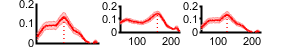

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
  figQuality(gcf,gca,[3 0.5])

  %print(gcf,'-dpdf')
  

  % overlay traces
  figure
subplot(1,3,1)
i = 3;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(cko(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 i = 7;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1413

x2_1 = 110

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
   patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y1_1 y1_1 0],'k','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[3 0.5])
  
  subplot(1,3,2)
i = 3;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 i = 7;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y2_1 x2_1] = nanmax(smooth(con(i).mean(50:225)))

y2_1 = 0.1177

x2_1 = 107

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'k';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
   patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y2_1 y2_1 0],'k','EdgeColor','none','FaceAlpha',0.1);
  figQuality(gcf,gca,[3 0.5])
  
  subplot(1,3,3)
i = 3;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(cko(i).mean(51:240)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'r';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 i = 7;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1413

x2_1 = 110

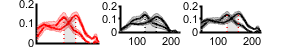

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y1_1 y1_1 0],'k','EdgeColor','none','FaceAlpha',0.1);

  figQuality(gcf,gca,[3 0.5])
   %print(gcf,'-dpdf')

   % plot of spatial location (supplement fig)
   
   conMeanMatx = [];
ckoMeanMatx = [];
for i = 1:10
    conMeanLoc(i) = nanmean([con1PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i),con7PeakLoc(i)]);
    conMeanMatx = [conMeanMatx;[con1PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i),con7PeakLoc(i)]];
    sterrConLoc(i) = nanstd([con1PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i),con7PeakLoc(i)])/sqrt(5);
    ckoMeanLoc(i) = nanmean([cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i)]);
    ckoMeanMatx = [ckoMeanMatx;[cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i)]];
    sterrckoLoc(i) = nanstd([cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i)])/sqrt(4);
end

figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMeanLoc-conMeanLoc(1),sterrConLoc)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,ckoMeanLoc-ckoMeanLoc(1),sterrckoLoc,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


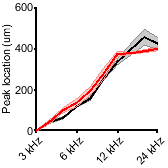

    c2.mainLine.LineWidth = 1.5;
ylim([0 600]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')
   
 genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mousecko = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 110×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     874.38
    {'con'}     {'M1'}     {'2' }     912.73
    {'con'}     {'M1'}     {'3' }     928.07
    {'con'}     {'M1'}     {'4' }      997.1
    {'con'}     {'M1'}     {'5' }     1035.5
    {'con'}     {'M1'}     {'6' }     1127.5
    {'con'}     {'M1'}     {'7' }     1250.2
    {'con'}     {'M1'}     {'8' }     1349.9
    {'con'}     {'M1'}     {'9' }     1411.3
    {'con'}     {'M1'}     {'10'}        NaN
    {'con'}     {'M2'}     {'1' }        NaN
    {'con'}     {'M2'}     {'2' }     891.54
    {'con'}     {'M2'}     {'3' }      914.4
    {'con'}     {'M2'}     {'4' }      990.6
    {'con'}     {'M2'}     {'5' }     1036.3
    {'con'}     {'M2'}     {'6' }       1143


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')  

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              75
    Fixed effects coefficients           2
    Random effects coefficients         21
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    788.91    800.37    -389.46          778.91  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF    pValue       Lower      Upper 
    {'(Intercept)' }        1091.1      51.657     21.122    73    8.013e-33     988.17    1194.1
    {'Genotype_cko'}        6.1237      10.293    0.59492    73      0.55373    -14.391    26.638

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type           

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta = 	1.0e+03 *

    1.0911
    0.0061


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat      DF        pValue        Lower      Upper 
    {'(Intercept)' }        1091.1      51.657     21.122    9.1719    4.3192e-09     974.59    1207.6
    {'Genotype_cko'}        6.1237      10.293    0.59492    9.8047       0.56537    -16.873    29.121


% distance from center of IC

cko1 = load('299_3_0dBprofilecenter.mat');
cko2 = load('386_3_0dBprofilecenter.mat');
cko3 = load('386_4_0dBprofilecenter.mat'); % no 6 kHz really, very very dim
cko4 = load('452_3_0dBprofilecenter.mat'); % meh
cko5 = load('412_2_0dBprofilecenter.mat');
cko6 = load('451_2_0dBprofilecenter.mat');
cko7 = load('350_2_0dBprofilecenter.mat');

con1 = load('308_1_0dBprofilecenter.mat');
con2 = load('308_3_0dBprofilecenter.mat'); % inf values
con3 = load('327_1_0dBprofilecenter.mat');
con4 = load('339_5_0dBprofilecenter.mat');
con5 = load('342_2_0dBprofilecenter.mat');
con6 = load('419_3_0dBprofilecenter.mat');

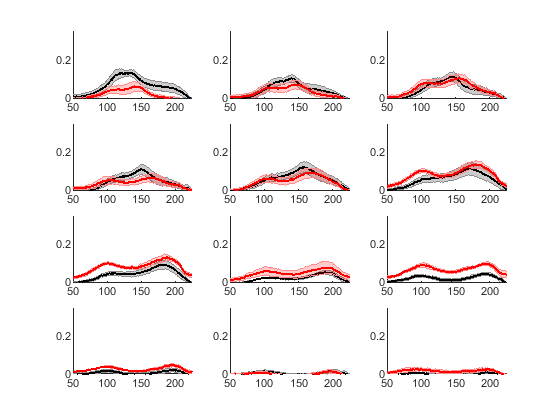


% all freq
figure
cko = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    cko(i).mean = nanmean([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';cko7.meanLIC(i).profileraw';],1)-0.1;
    con(i).mean = nanmean([con1.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)-0.1;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    cko(i).std = nanstd([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';cko7.meanLIC(i).profileraw';],1)/sqrt(5);
    con(i).std = nanstd([con1.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)/sqrt(6);
   % tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    xlim([50 225])
end

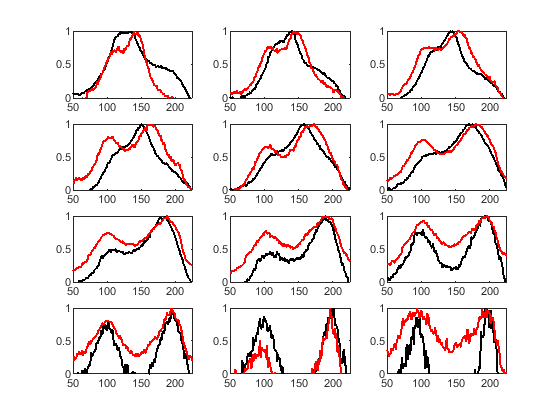


% all freq normalized

% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(51:225));
    hold on
    plot(cko(i).mean/nanmax(cko(i).mean(50:225)),'r','LineWidth',1.5)
    cko(i).norm = cko(i).mean/nanmax(cko(i).mean(50:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
   % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end

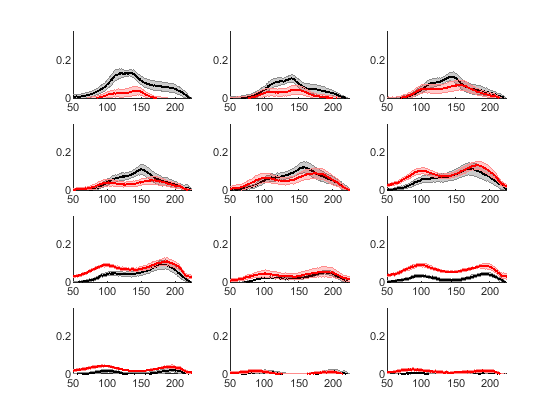


% plus extras without 4.5 response
figure
ckoHF = struct();
con = struct();
tecta = struct();
x = [1:1:250];
for i = 1:12
    ckoHF(i).mean = nanmean([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';cko5.meanLIC(i).profileraw';cko6.meanLIC(i).profileraw';cko7.meanLIC(i).profileraw';],1)-0.1;
    con(i).mean = nanmean([con1.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)-0.1;
    %tecta(i).mean = nanmean([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)-0.1;
    ckoHF(i).std = nanstd([cko1.meanLIC(i).profileraw';cko2.meanLIC(i).profileraw';cko3.meanLIC(i).profileraw';cko4.meanLIC(i).profileraw';cko5.meanLIC(i).profileraw';cko6.meanLIC(i).profileraw';cko7.meanLIC(i).profileraw';],1)/sqrt(7);
    con(i).std = nanstd([con1.meanLIC(i).profileraw';con2.meanLIC(i).profileraw';con3.meanLIC(i).profileraw';con4.meanLIC(i).profileraw';con5.meanLIC(i).profileraw';con6.meanLIC(i).profileraw';],1)/sqrt(6);
   % tecta(i).std = nanstd([tecta1.meanLIC(i).profileraw';tecta2.meanLIC(i).profileraw'],1)/sqrt(2);
    subplot(4,3,i)
    c1 = shadedErrorBar(x,con(i).mean,con(i).std);
    c1.mainLine.LineWidth = 1.5;
    hold on
    c1 = shadedErrorBar(x,ckoHF(i).mean,ckoHF(i).std,'lineprops','r');
    c1.mainLine.LineWidth = 1.5;
     % c1 = shadedErrorBar(x,tecta(i).mean,tecta(i).std,'lineprops','b');
    %c1.mainLine.LineWidth = 1.5;
    ylim([0 0.35])
    xlim([50 225])
end

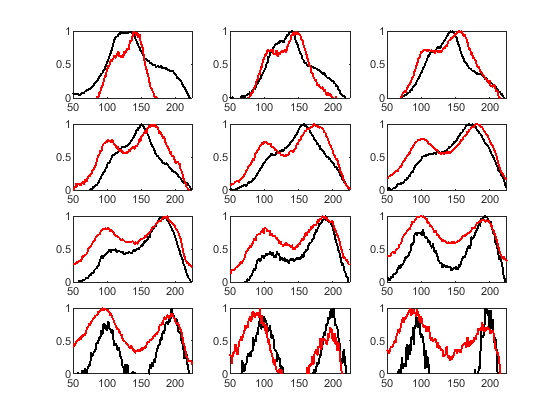


% normalized plots 
figure
for i = 1:12
    subplot(4,3,i)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    con(i).norm = con(i).mean/nanmax(con(i).mean(51:225));
    hold on
    plot(ckoHF(i).mean/nanmax(ckoHF(i).mean(50:225)),'r','LineWidth',1.5)
    ckoHF(i).norm = ckoHF(i).mean/nanmax(ckoHF(i).mean(50:225));
   % plot(tecta(i).mean/nanmax(tecta(i).mean(50:225)),'b','LineWidth',1.5)
   % tecta(i).norm = tecta(i).mean/nanmax(tecta(i).mean(50:225));
    ylim([0 1])
    xlim([50 225])
end


% mean 4.5 kHz loc (only those with 4.5 responses)
i = 3; % 4.5 khz response
figure
subplot(1,3,1)
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:225)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1019

x2_1 = 106

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y2_1 y2_1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])
subplot(1,3,2)
i = 6;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:225)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,ckoHF(i).mean,ckoHF(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(ckoHF(i).mean(50:225)))

y2_1 = 0.1310

x2_1 = 132

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y2_1 y2_1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])
    subplot(1,3,3)
    i = 3;
 c1 = shadedErrorBar(x,con(i).mean,con(i).std);
 c1.mainLine.LineWidth = 1.5;
 hold on
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:225)));
 l1_1 = line([x1_1+50 x1_1+50],[0,y1_1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 c1 = shadedErrorBar(x,cko(i).mean,cko(i).std,'lineprops','r');
 c1.mainLine.LineWidth = 1.5;
 [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1019

x2_1 = 106

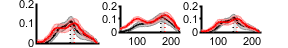

 l2_1 = line([x2_1+49 x2_1+49],[0,y2_1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 0.2])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 y2_1 y2_1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])

%print(gcf,'-dpdf')   
  % normalized
  
  i = 3; % 4.5 khz response
figure
subplot(1,3,1)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(cko(i).mean/nanmax(cko(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])
subplot(1,3,2)
i = 6;
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(ckoHF(i).mean/nanmax(ckoHF(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
 [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:225)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
 [y2_1 x2_1] = nanmax(smooth(ckoHF(i).mean(50:225)))

y2_1 = 0.1310

x2_1 = 132

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])
    subplot(1,3,3)
    i = 3;
subplot(1,3,3)
    plot(con(i).mean/nanmax(con(i).mean(51:225)),'k','LineWidth',1.5)
    hold on
    plot(cko(i).mean/nanmax(cko(i).mean(50:225)),'r','LineWidth',1.5)
    ylim([0 1])
    xlim([50 225])
     [y1_1 x1_1] = nanmax(smooth(con(i).mean(51:225)));
 l1_1 = line([x1_1+50 x1_1+50],[0,1]);
 l1_1.Color = 'k';
 l1_1.LineStyle = ':';
 l1_1.LineWidth = 1;
  [y2_1 x2_1] = nanmax(smooth(cko(i).mean(50:225)))

y2_1 = 0.1019

x2_1 = 106

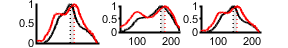

 l2_1 = line([x2_1+49 x2_1+49],[0,1]);
 l2_1.Color = 'r';
 l2_1.LineStyle = ':';
 l2_1.LineWidth = 1;
  ylim([0 1])
 xlim([50 225])
    patch([x1_1+50 x1_1+50 x2_1+49 x2_1+49], [0 1 1 0],'k','EdgeColor','none','FaceAlpha',0.1);
    figQuality(gcf,gca,[3 0.5])

% print(gcf,'-dpdf') 

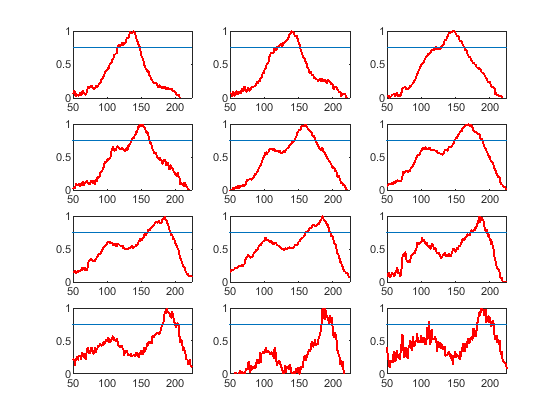

% profile relatve to IC center
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko1BW = (cko1.meanLIC(i).profileraw'-0.1)/(max(cko1.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko1BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko1bandW(i) = sum(smooth(cko1BW(90:225))> perctile)*scale;
    [cko1Peak(i) cko1PeakLoc(i)] = max(smooth(cko1.meanLIC(i).profileraw(50:225)'));
    cko1PeakLoc(i) = cko1PeakLoc(i)+49;
end

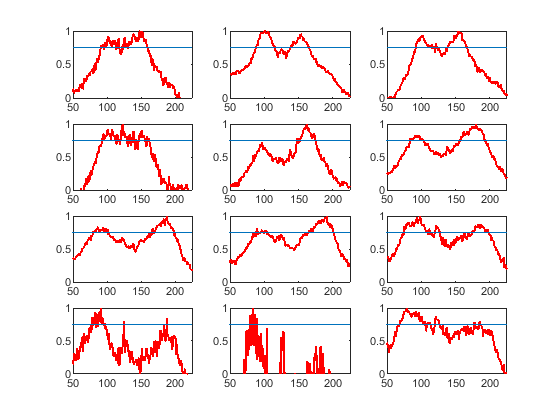

cko1PeakLoc =  cko1PeakLoc*scale;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko2BW = (cko2.meanLIC(i).profileraw'-0.1)/(max(cko2.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko2BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko2bandW(i) = sum(smooth(cko2BW(90:225))> perctile)*scale;
    [cko2Peak(i) cko2PeakLoc(i)] = max(smooth(cko2.meanLIC(i).profileraw(50:225)'));
    cko2PeakLoc(i) = cko2PeakLoc(i)+49;
end

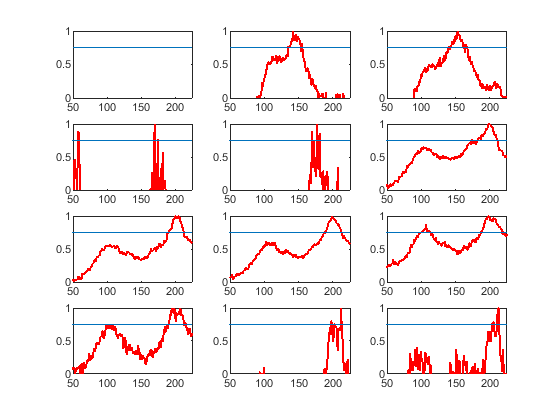

cko2PeakLoc =  cko2PeakLoc*scale;
cko2PeakLoc(1:2) = NaN;
cko2PeakLoc(4) = NaN;
cko2PeakLoc(9:10) = NaN;
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko3BW = (cko3.meanLIC(i).profileraw'-0.1)/(max(cko3.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko3BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko3bandW(i) = sum(smooth(cko3BW(90:225))> perctile)*scale;
    [cko3Peak(i) cko3PeakLoc(i)] = max(smooth(cko3.meanLIC(i).profileraw(50:225)'));
    cko3PeakLoc(i) = cko3PeakLoc(i)+49;
end

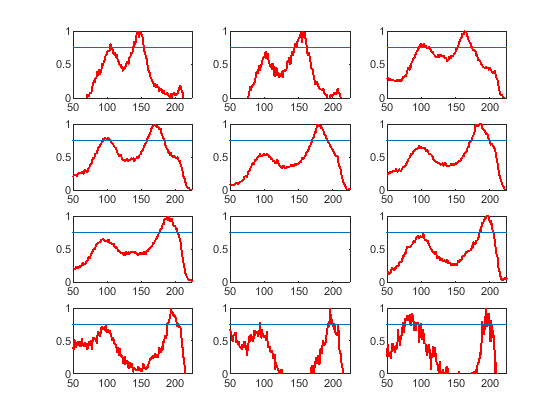

cko3PeakLoc =  cko3PeakLoc*scale;
cko3PeakLoc(1) = NaN;
cko3PeakLoc(4:5) = NaN;
cko3PeakLoc(10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko4BW = (cko4.meanLIC(i).profileraw'-0.1)/(max(cko4.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko4BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko4bandW(i) = sum(smooth(cko4BW(90:225))> perctile)*scale;
    [cko4Peak(i) cko4PeakLoc(i)] = max(smooth(cko4.meanLIC(i).profileraw(50:225)'));
    cko4PeakLoc(i) = cko4PeakLoc(i)+49;
end

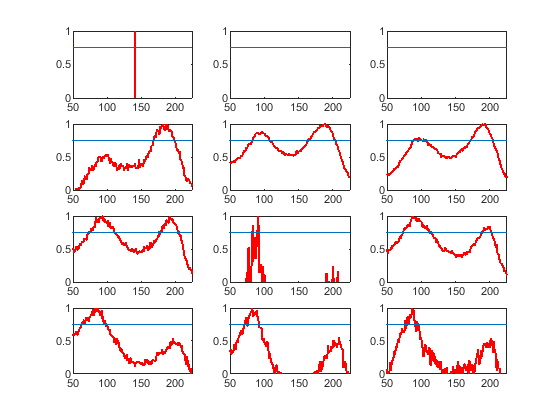

cko4PeakLoc =  cko4PeakLoc*scale;
cko4PeakLoc(8) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko5BW = (cko5.meanLIC(i).profileraw'-0.1)/(max(cko5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko5BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko5bandW(i) = sum(smooth(cko5BW(90:225))> perctile)*scale;
    [cko5Peak(i) cko5PeakLoc(i)] = max(smooth(cko5.meanLIC(i).profileraw(50:225)'));
    cko5PeakLoc(i) = cko5PeakLoc(i)+49;
end

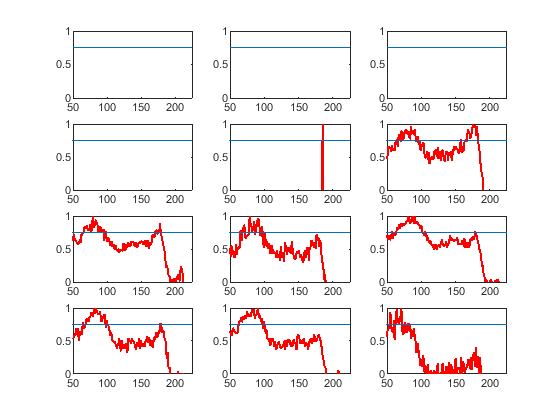

cko5PeakLoc =  cko5PeakLoc*scale;

cko5PeakLoc(1:3) = NaN;
cko5PeakLoc(7:10) = NaN;
% don't use 6
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko6BW = (cko6.meanLIC(i).profileraw'-0.1)/(max(cko6.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko6BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko6bandW(i) = sum(smooth(cko6BW(90:225))> perctile)*scale;
    [cko6Peak(i) cko6PeakLoc(i)] = max(smooth(cko6.meanLIC(i).profileraw(50:225)'));
    cko6PeakLoc(i) = cko6PeakLoc(i)+49;
end

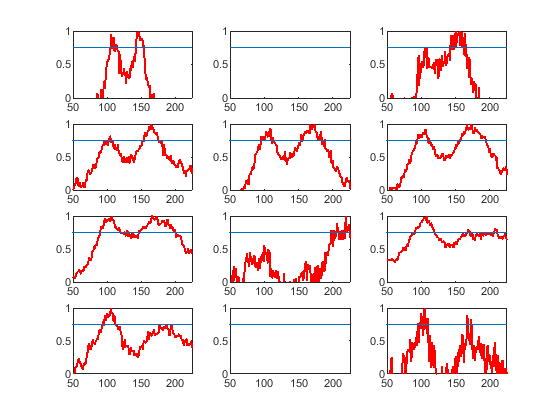

cko6PeakLoc =  cko6PeakLoc*scale;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.68; %um/pixel
for i = 1:12
    subplot(4,3,i)
    cko7BW = (cko7.meanLIC(i).profileraw'-0.1)/(max(cko7.meanLIC(i).profileraw(50:225)'-0.1));
    plot(cko7BW,'r','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    cko7bandW(i) = sum(smooth(cko7BW(90:225))> perctile)*scale;
    [cko7Peak(i) cko7PeakLoc(i)] = max(smooth(cko7.meanLIC(i).profileraw(50:225)'));
    cko7PeakLoc(i) = cko7PeakLoc(i)+49;
end

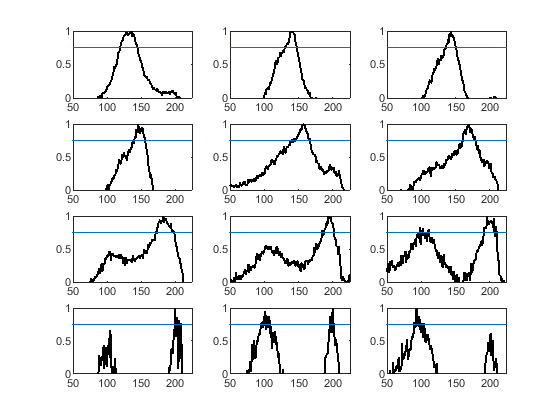

cko7PeakLoc =  cko7PeakLoc*scale;
cko7PeakLoc(1:3) = NaN;
cko7PeakLoc(7:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.67; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con1BW = (con1.meanLIC(i).profileraw'-0.1)/(max(con1.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con1BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con1bandW(i) = sum(smooth(con1BW(90:225))> perctile)*scale;
    [con1Peak(i) con1PeakLoc(i)] = max(smooth(con1.meanLIC(i).profileraw(50:225)'));
    con1PeakLoc(i) = con1PeakLoc(i)+49;
end

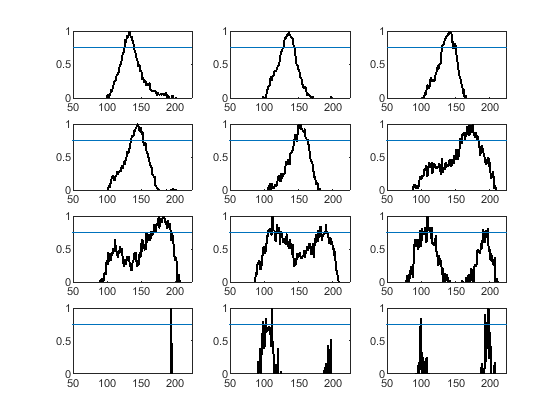

con1PeakLoc =  con1PeakLoc*scale;
con1bandW(10) = NaN;
con1PeakLoc(10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.67; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con2BW = (con2.meanLIC(i).profileraw'-0.1)/(max(con2.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con2BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con2bandW(i) = sum(smooth(con2BW(90:225))> perctile)*scale;
    [con2Peak(i) con2PeakLoc(i)] = max(smooth(con2.meanLIC(i).profileraw(50:225)'));
    con2PeakLoc(i) = con2PeakLoc(i)+49;
end

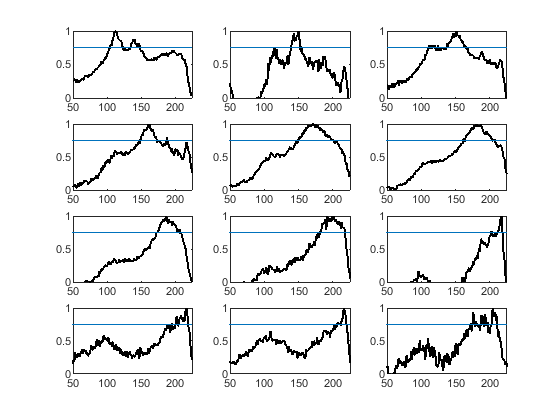

con2PeakLoc =  con2PeakLoc*scale;
con2PeakLoc(8:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.62; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con3BW = (con3.meanLIC(i).profileraw'-0.1)/(max(con3.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con3BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con3bandW(i) = sum(smooth(con3BW(90:225))> perctile)*scale;
    [con3Peak(i) con3PeakLoc(i)] = max(smooth(con3.meanLIC(i).profileraw(50:225)'));
    con3PeakLoc(i) = con3PeakLoc(i)+49;
end

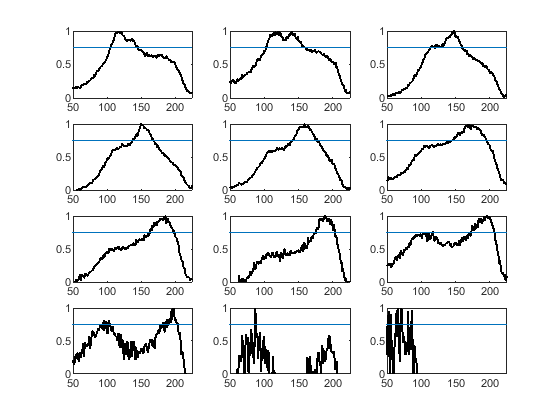

con3PeakLoc =  con3PeakLoc*scale;
con3PeakLoc(1) = NaN;
con3PeakLoc(9:10) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.65; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con4BW = (con4.meanLIC(i).profileraw'-0.1)/(max(con4.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con4BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con4bandW(i) = sum(smooth(con4BW(90:225))> perctile)*scale;
    [con4Peak(i) con4PeakLoc(i)] = max(smooth(con4.meanLIC(i).profileraw(50:225)'));
    con4PeakLoc(i) = con4PeakLoc(i)+49;
end

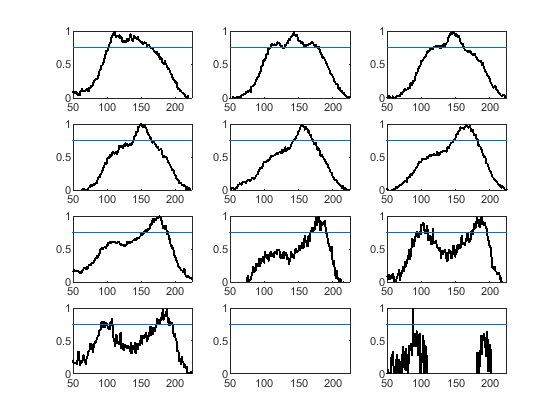

con4PeakLoc =  con4PeakLoc*scale;
con4PeakLoc(1:2) = NaN;
con4PeakLoc(10) = NaN;
figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.69; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con5BW = (con5.meanLIC(i).profileraw'-0.1)/(max(con5.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con5BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con5bandW(i) = sum(smooth(con5BW(90:225))> perctile)*scale;
    [con5Peak(i) con5PeakLoc(i)] = max(smooth(con5.meanLIC(i).profileraw(50:225)'));
    con5PeakLoc(i) = con5PeakLoc(i)+49;
end

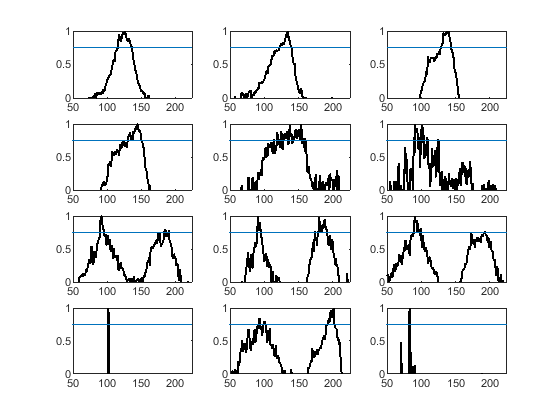

con5PeakLoc =  con5PeakLoc*scale;
con5PeakLoc(1) = NaN;

figure
perctile = 0.75; % 75th percentile, normalized
scale = 7.61; %um/pixel
for i = 1:12
    subplot(4,3,i)
    con6BW = (con6.meanLIC(i).profileraw'-0.1)/(max(con6.meanLIC(i).profileraw(50:225)'-0.1));
    plot(con6BW,'k','LineWidth',1.5)
    hold on
    line([0 250],[perctile perctile])
    ylim([0 1])
    xlim([50 225])
    con6bandW(i) = sum(smooth(con6BW(90:225))> perctile)*scale;
    [con6Peak(i) con6PeakLoc(i)] = max(smooth(con6.meanLIC(i).profileraw(50:225)'));
    con6PeakLoc(i) = con6PeakLoc(i)+49;
end

con6PeakLoc =  con6PeakLoc*scale;
con6PeakLoc(6:10) = NaN;


% peak location relative to medial IC   

conMeanMatx = [];
ckoMeanMatx = [];
for i = 1:10
    conMeanLoc(i) = nanmean([con1PeakLoc(i),con2PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i)]);
    conMeanMatx = [conMeanMatx;[con1PeakLoc(i),con2PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i)]];
    sterrConLoc(i) = nanstd([con1PeakLoc(i),con2PeakLoc(i),con3PeakLoc(i),con4PeakLoc(i),con5PeakLoc(i),con6PeakLoc(i)])/sqrt(7);
    ckoMeanLoc(i) = nanmean([cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i),cko7PeakLoc(i)]);
    ckoMeanMatx = [ckoMeanMatx;[cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i),cko7PeakLoc(i)]];
    sterrckoLoc(i) = nanstd([cko1PeakLoc(i),cko2PeakLoc(i),cko3PeakLoc(i),cko4PeakLoc(i),cko5PeakLoc(i),cko7PeakLoc(i)])/sqrt(6);
end

figure
k = 1:1:10;
conditions = {'3 kHz', '6 kHz', '12 kHz', '24 kHz'};
    c1 = shadedErrorBar(k,conMeanLoc-(125*7.65),sterrConLoc)

c1 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


    c1.mainLine.LineWidth = 1.5;
    hold on
    c2 = shadedErrorBar(k,ckoMeanLoc-(125*7.65),sterrckoLoc,'lineprops','r')

c2 = struct with fields:
    mainLine: [1×1 Line]
       patch: [1×1 Patch]
        edge: [1×2 Line]


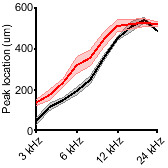

    c2.mainLine.LineWidth = 1.5;
ylim([0 600]);
xlim([1 10]);
xticks([1 4 7 10])
xticklabels(conditions)
ylabel('Peak location (um)')
%xticklabels(conditions)
xtickangle(45)
figQuality(gcf,gca,[1.75 1.75])

%print(gcf,'-dpdf')

 genoBasecon = {'con','con','con','con','con','con','con','con','con','con'};
genoBasecko = {'cko','cko','cko','cko','cko','cko','cko','cko','cko','cko'};

geno = [genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecon,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko,genoBasecko]';
mousecon = {'M1','M1','M1','M1','M1','M1','M1','M1','M1','M1','M2','M2','M2','M2','M2','M2','M2','M2','M2','M2','M3','M3','M3','M3','M3','M3','M3','M3','M3','M3','M4','M4','M4','M4','M4','M4','M4','M4','M4','M4','M5','M5','M5','M5','M5','M5','M5','M5','M5','M5','M6','M6','M6','M6','M6','M6','M6','M6','M6','M6'};
mousecko = {'M8','M8','M8','M8','M8','M8','M8','M8','M8','M8','M9','M9','M9','M9','M9','M9','M9','M9','M9','M9','M10','M10','M10','M10','M10','M10','M10','M10','M10','M10','M11','M11','M11','M11','M11','M11','M11','M11','M11','M11','M12','M12','M12','M12','M12','M12','M12','M12','M12','M12','M13','M13','M13','M13','M13','M13','M13','M13','M13','M13'};
mouse = [mousecon,mousecko]';
locationBase = {'1' '2','3','4','5','6','7','8','9','10'}; 
location = [locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase,locationBase]';
BW = [conMeanMatx(:,1)',conMeanMatx(:,2)',conMeanMatx(:,3)',conMeanMatx(:,4)',conMeanMatx(:,5)',conMeanMatx(:,6)',ckoMeanMatx(:,1)',ckoMeanMatx(:,2)',ckoMeanMatx(:,3)',ckoMeanMatx(:,4)',ckoMeanMatx(:,5)',ckoMeanMatx(:,6)']';

tbl = table(geno,mouse,location,BW,'VariableNames',{'Genotype','Mouse','Location','BW'})

tbl = 120×4 table
    Genotype    Mouse     Location      BW  
    ________    ______    ________    ______

    {'con'}     {'M1'}     {'1' }     1027.8
    {'con'}     {'M1'}     {'2' }     1073.8
    {'con'}     {'M1'}     {'3' }     1096.8
    {'con'}     {'M1'}     {'4' }     1158.2
    {'con'}     {'M1'}     {'5' }     1204.2
    {'con'}     {'M1'}     {'6' }     1288.6
    {'con'}     {'M1'}     {'7' }       1419
    {'con'}     {'M1'}     {'8' }     1495.7
    {'con'}     {'M1'}     {'9' }     1518.7
    {'con'}     {'M1'}     {'10'}        NaN
    {'con'}     {'M2'}     {'1' }     1027.8
    {'con'}     {'M2'}     {'2' }     1035.5
    {'con'}     {'M2'}     {'3' }     1089.1
    {'con'}     {'M2'}     {'4' }     1104.5
    {'con'}     {'M2'}     {'5' }     1165.8
    {'con'}     {'M2'}     {'6' }     1326.9


lme = fitlme(tbl,'BW~Genotype+(1|Location)+(1|Mouse)','FitMethod','reml')  

lme = Linear mixed-effects model fit by REML

Model information:
    Number of observations              80
    Fixed effects coefficients           2
    Random effects coefficients         22
    Covariance parameters                3

Formula:
    BW ~ 1 + Genotype + (1 | Location) + (1 | Mouse)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    872.88    884.67    -431.44          862.88  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat     DF    pValue        Lower     Upper 
    {'(Intercept)' }        1258.1      55.804    22.544    78    6.6272e-36      1147    1369.2
    {'Genotype_cko'}        90.268      32.588    2.7699    78     0.0070044    25.389    155.15

Random effects covariance parameters (95% CIs):
Group: Location (10 Levels)
    Name1                  Name2                  Type           Est

[beta, betanames, stats] = fixedEffects(lme,'DFMethod','satterthwaite')

beta = 	1.0e+03 *

    1.2581
    0.0903


betanames = 2×1 table
          Name      
    ________________

    {'(Intercept)' }
    {'Genotype_cko'}


stats =     Fixed effect coefficients: DFMethod = 'Satterthwaite', Alpha = 0.05

    Name                    Estimate    SE        tStat     DF        pValue        Lower     Upper 
    {'(Intercept)' }        1258.1      55.804    22.544    12.319    2.1767e-11    1136.8    1379.3
    {'Genotype_cko'}        90.268      32.588    2.7699    9.5661      0.020585    17.207    163.33
